# **IO110 - Analog Output**

This example shows you how to do a test with the IO110 I/O module in order to verify the basic functionality of some of the analog output channels.

The IO110 is a 16-bit analog module with 32 single-ended analog output channels. 

The Simulink model features the [IO110 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io110_setup) and [IO110 Analog output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io110_analog_output) blocks.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO110 module installed

- 68-pin terminal board for the IO110

- Connector cables from the I/O modules to the terminal boards

- Oscilloscope

### Test Setup

This example outputs a sine wave signal on the analog voltage outputs that can be visualized using an oscilloscope. On the digital part, a pulse generator is connected to the digital outputs.

On the terminal board of the IO110 I/O module, connect Pin 1, the analog output channel 1, to the probe input clip and Pin 35, the ground pin, to the ground clip of the oscilloscope. 

The wiring is shown on the picture below:

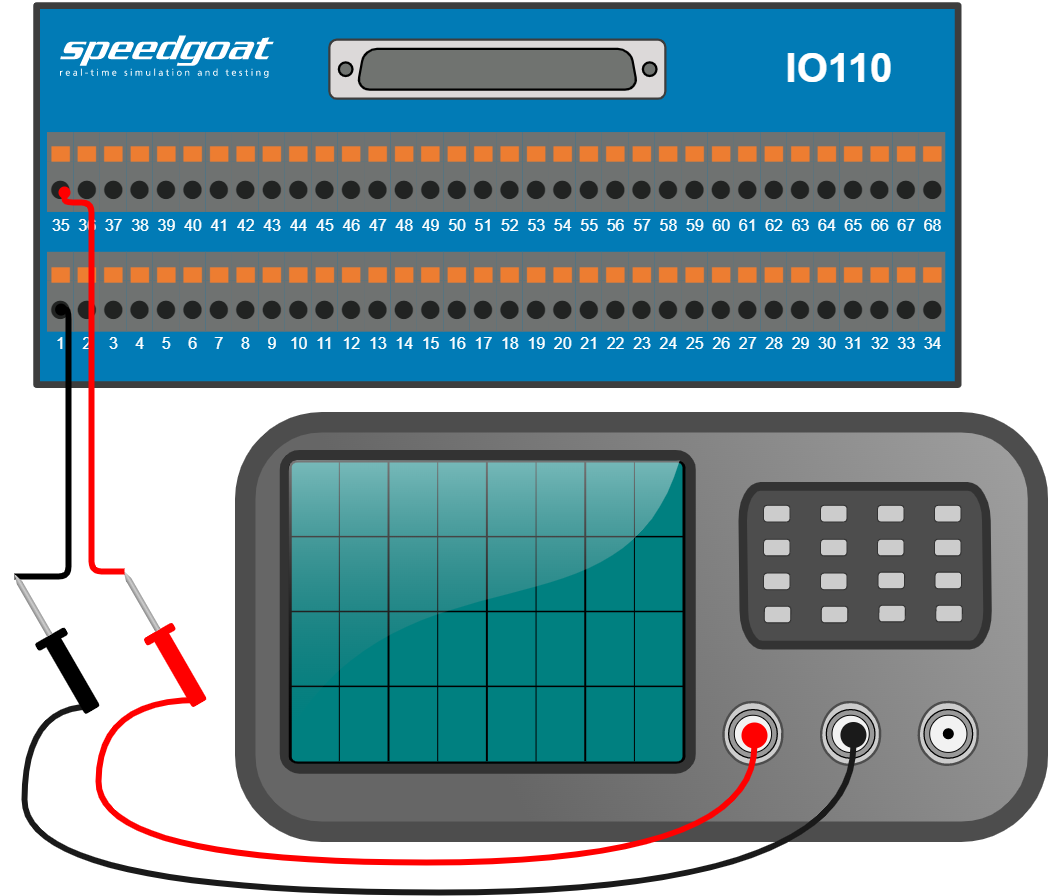

The same steps can be repeated with pin 9, pin17 and pin 25 to observe the different voltage ranges of the I/O Module.

[IO110 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io110_pin_mapping)

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO110_AnalogOutputTest';
open_system(modelName);

### Model Description

This example outputs four sine wave signals on the analog voltage outputs. According to the channels' voltage ranges set in the Setup blocks, the signals have different amplitudes and may possess only positive values. The Voltage is measured on the oscilloscope

Analog output channels 1 (0..5V), 9 (+-5V), 17 (0..10V) and 25 (+-10V) are enabled in the Setup block.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode   

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

In the below scopes you can see the four sine signals  from analog output channels 1, 9, 17 and 25 sequentially measured on the oscilloscope .

The amplitudes used for the analog output signals indicate the different channels seen in the scopes. Please note that for channel 1 and 17, the output setting is unipolar, which can be observed in the measurements since only the positive part of the sinus is observable.

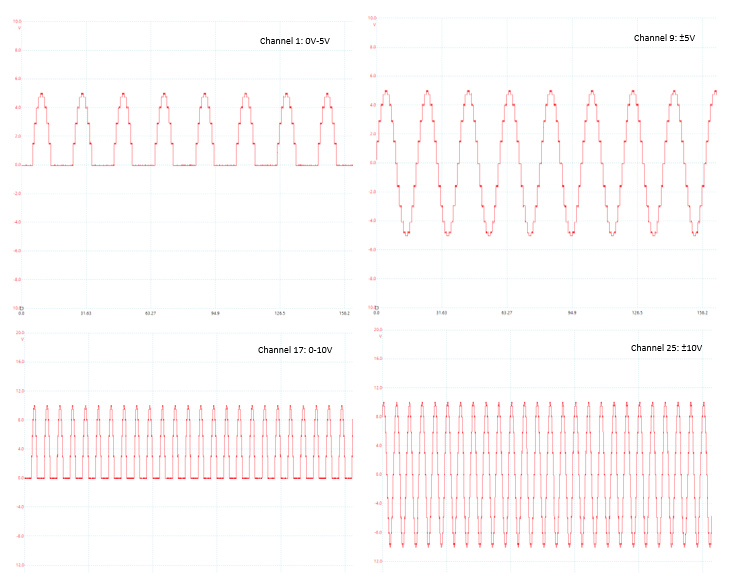

## Additional References

- [IO110 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io110)